# **TP4 - **

## Exercice 54 p 31

On veut simuler une entrée d'amplitude 0,5, avec la fonction stepDataOptions

k = 1;
M = 1;
F = 1;
s = tf("s");
xi = 1/2 * (F / (sqrt(M * k)));
omega = sqrt(k/M);

K est le gain statique

K = 1/k

K = 1

On définit Y = X(s)F(s);

Y = (k * omega ^2) / (s ^ 2 + 2 * xi * omega *s + omega^2);

Create a transfer function model.

Create an option set for step to specify input offset and step amplitude level.

opt = stepDataOptions('StepAmplitude',0.5);

Calculate the step response using the specified options.

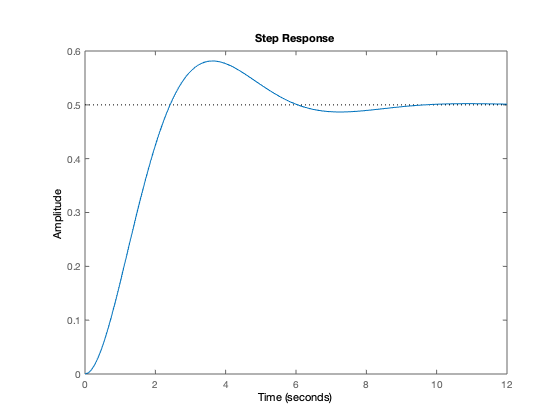

step(Y,opt)

## Exercice donée 

                3s + 1

Y(s) @ 

           2s^2 + s + 1

- Calculer les zéros et les pôles.

- Trouver l'original temporal de Y(s)

### Première : 1.

s = tf("s");
Y = (3*s + 1) / (2 * s ^ 2 + s + 1) 


Y =
 
     3 s + 1
  -------------
  2 s^2 + s + 1
 
Continuous-time transfer function.



[zero, pole, gain] = zpkdata(Y)

zero = 1×1 cell array
    {[-0.3333]}


pole = 1×1 cell array
    {2×1 double}


gain = 1.5000

### Dexième 

Sur Matlab, il est impossible de trouver l'original temporel. On peut le simuler via le impulse.

## Exercice 59 p 32